# Calculating Position of the sun in the sky

#### Transform any geodetic location into a local system.

**Step 1**: Define your favorite location in geodetic coordinates 

**Step 2:** Transform those coordinates from spherical to cartesian coordinates 

**Step 3:** Use the defined transformation to take precession, nutation and local time into account 

PRE_INIT();
phi = -70.6734; % latitude of Neumayer Station in degrees
lambda = -8.2741; % longitude of Neumayer Station in degrees
year = 2024; % Desired year you want to inspect
month = 06; % Desired month you want to inspect
day = 23; % Desired day you want to inspect
ut1 = 12; % Exact time you want to inspect
alpha = 0;
delta = 0;
r_i = zeros(3,1);

## Zeitberechnung


% Convert the date to julian centuries
[t, mjd, jd] = geodesy.GDS_JULIANC(year, month, day, ut1);
[gast, gmst] = geodesy.GDS_JUL_TO_GAST(ut1, t);

% a = 6378137; % WGS-84 semi-major axis in meters
% e = 0.08181919; % WGS-84 eccentricity
disp("Starte Simulation mit Eingangsdaten:")

Starte Simulation mit Eingangsdaten:


disp("Breite: "+ phi)

Breite: -70.6734


disp("Länge: "+ lambda)

Länge: -8.2741


disp("Datum: "+day+"/"+month+"/"+year+" - "+floor(ut1)+":00")

Datum: 23/6/2024 - 12:00


disp("Julianisches Jahrhundert: "+t)

Julianisches Jahrhundert: 0.24476


disp("GAST: "+gast)

GAST: 6.1431


disp("GMST: "+gmst)

GMST: 6.1432



[r_i(1),r_i(2),r_i(3)] = sph2cart(deg2rad(alpha), deg2rad(delta), 1);


## Nutation Precession


% Berechnung der Nutation
[eps0, deleps, delpsi] = geodesy.GDS_NUTATION(t);
disp("Nutation:")

Nutation:


disp("  Mittlerer Winkel der Ekliptik [Epsilon]: "+eps0)

  Mittlerer Winkel der Ekliptik [Epsilon]: 23.4361


disp("  Nutation in Schiefe [Delta Eps]: "+deleps)

  Nutation in Schiefe [Delta Eps]: 0.0023472


disp("  Nutation in Länge [Delta Psi]: "+delpsi)

  Nutation in Länge [Delta Psi]: -0.00093787



% Berechnung der Präzession seit J2000
[za, thetaa, zetaa] = geodesy.GDS_PRECESSION(t);
disp("Präzession:")

Präzession:


disp("  Zenitwinkel [z]: "+za)

  Zenitwinkel [z]: 0.15682


disp("  Nutation in Schiefe [Theta]: "+thetaa)

  Nutation in Schiefe [Theta]: 0.13627


disp("  Nutation in Länge [Ceta]: "+zetaa)

  Nutation in Länge [Ceta]: 0.1568



% Zusammensetzen der Rotationsmatrizen
N = rotx(-eps0-deleps)*rotz(-delpsi)*rotx(eps0);
P = rotz(-za)*roty(thetaa)*rotz(-zetaa);
r_g = roty(90-phi)*rotz(lambda)*rotz(gast/24)*N*P*r_i;

## Plotting inertial Results

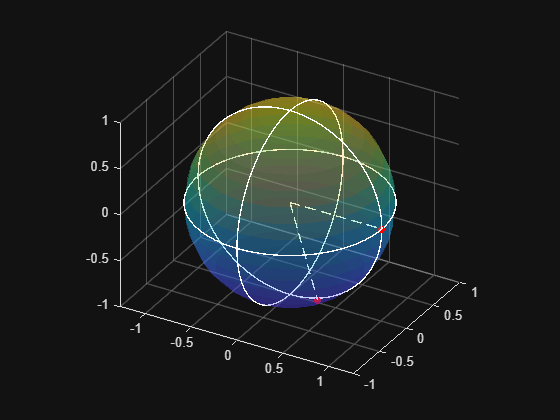

tiledlayout(1,2);
POST_INIT();
[u, v, w] = ellipsoid(0,0,0,1,1,1,20);
surf(u,v,w, 'EdgeColor', 'none', 'FaceAlpha', 0.3)

% Define the circle in the xy-plane
theta = linspace(0, 2*pi, 100);
x = cos(theta);
y = sin(theta);
z = zeros(size(theta)); % z-coordinate is zero for the xy-plane
plot3(x, y, z, 'w', 'LineWidth', 1);

% Define the GM
theta = linspace(0, 2*pi, 100);
x = cos(theta);
z = sin(theta);
y = zeros(size(theta)); % z-coordinate is zero for the xy-plane
plot3(x, y, z, 'w', 'LineWidth', 1);

% Define the GM
theta = linspace(0, 2*pi, 100);
y = cos(theta);
z = sin(theta);
x = zeros(size(theta)); % z-coordinate is zero for the xy-plane
plot3(x, y, z, 'w', 'LineWidth', 1);

sun = POINT_TO_VECTOR(r_i(1),r_i(2),r_i(3));
HOLD_PLOT_VEC3(sun)
[x,y,z] = sph2cart(deg2rad(lambda), deg2rad(phi), 1);
pos = POINT_TO_VECTOR(x,y,z);
HOLD_PLOT_VEC3(pos)
hold off;

## Plotting local results

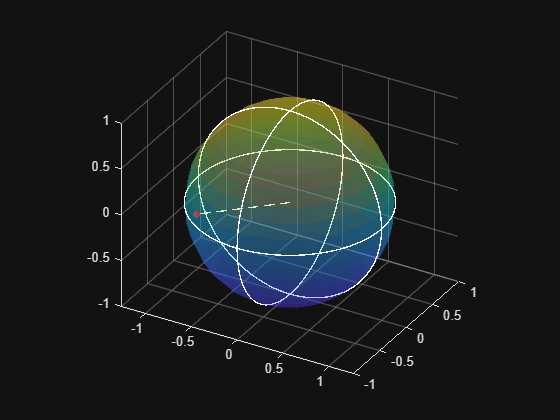


nexttile;
hold on;
POST_INIT();
[u, v, w] = ellipsoid(0,0,0,1,1,1,20);
surf(u,v,w, 'EdgeColor', 'none', 'FaceAlpha', 0.3)

% Define the circle in the xy-plane
theta = linspace(0, 2*pi, 100);
x = cos(theta);
y = sin(theta);
z = zeros(size(theta)); % z-coordinate is zero for the xy-plane
plot3(x, y, z, 'w', 'LineWidth', 1);

% Define the GM
theta = linspace(0, 2*pi, 100);
x = cos(theta);
z = sin(theta);
y = zeros(size(theta)); % z-coordinate is zero for the xy-plane
plot3(x, y, z, 'w', 'LineWidth', 1);

% Define the GM
theta = linspace(0, 2*pi, 100);
y = cos(theta);
z = sin(theta);
x = zeros(size(theta)); % z-coordinate is zero for the xy-plane
plot3(x, y, z, 'w', 'LineWidth', 1);
center = POINT_TO_VECTOR(r_g(1),r_g(2),r_g(3));
HOLD_PLOT_VEC3(center)
hold off;